# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0151   -0.0626   -0.0091   -0.0315   -0.0157   -0.0147   -0.0156   -0.0148   -0.0147   -0.0152   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151   -0.0151
   -0.0857   -0.0952   -0.0914   -0.0872   -0.0867   -0.0851   -0.0864   -0.0862   -0.0855   -0.0857   -0.0858   -0.0857   -0.0856   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0.0857   -0

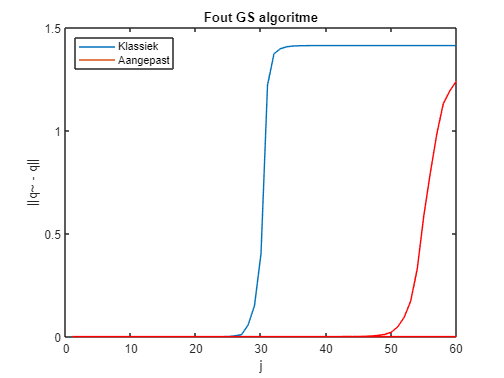


% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') % fout is exponentieel ma geen idee waarom

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0017    0.0104    0.0098
   -0.1006   -0.1629   -0.0999
    0.1120    0.0467    0.1053
    0.0163    0.0176    0.0310
   -0.1460   -0.1614   -0.1478
   -0.0556   -0.0529   -0.0939
   -0.0477   -0.1007   -0.0361
    0.0509    0.0533    0.0652
    0.0607    0.0514    0.0570
   -0.0090    0.0506    0.0019



e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)


% Oefening 9
m = 200;
n = 50;
k = 5;

B = randn(m,n);
[Q,~] = qr(B,0);

V = randn(n) % change this to orthogonal matrix

V =     1.3482   -0.0496   -0.5116   -0.5135    1.4546   -0.8499    0.8456    1.3695   -0.5902    0.2986   -1.0279    0.3345    0.4028   -0.5024   -0.4694    0.1120   -0.3974    0.6943    0.7550    0.1139    1.1106    0.0675   -1.1387    0.4599   -0.3011   -0.4938    1.9514    0.7981   -0.2975    0.1328   -1.8009    0.4701   -1.5754    1.0573   -0.6063    1.5772   -0.3070   -0.6618   -0.3636   -0.1565   -0.9237   -0.4287    0.6083   -1.1543    0.3750    0.9302   -0.3403   -0.3555    2.3743    0.7802
    0.1024   -0.2638   -0.7137   -0.5733   -0.8433   -1.2825   -2.4986    0.9350    0.4352    0.0475   -1.7553   -1.0193   -1.2054    0.0301   -0.9575   -0.6531   -1.4150    0.0347   -1.4181   -0.6968    0.7135   -0.8280    0.6350   -0.0810   -0.7964    0.4254   -1.4095   -1.1091   -1.4940    1.3368   -1.2637    0.8692    0.5852    1.3417    1.5650    1.0342   -0.6992   -0.6716   -0.5067   -0.3711   -1.3836    0.0096    0.7780   -1.3671    0.6703   -0.8793    1.3411    1.4039    1.1095    0


D = diag(2.^linspace(0,k,n)) % linspace returns n evenly spaced values between 0 and k

D =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0733         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


A = Q*D*V;

A =    11.0076  -11.2590    6.9805    3.7577   -8.9544   -7.1192   -0.5272    1.6802   -4.0355    3.1822   -1.2918   -2.7119   -2.7158    3.4946   -1.3765    5.3841   -0.0013   -5.9226   -4.2073   -2.4988    6.7455   -2.2185    2.3912   -1.3478   -1.1791    8.6559    0.3490   -7.6714    3.5347    1.3114    4.0036    6.4623    5.6963    6.0775    2.5505   -2.9803    9.1229    0.6538   -8.7286    6.7432   -3.6021   -1.9999   -0.7929    2.5439    1.5093    0.0363   -4.5653    6.3756   -1.6732    3.5932
   -7.6876   -0.0476   -1.6014    2.6856    0.7042   -2.8617   -1.7700   -0.8576   -6.5084    3.6117   -3.9011    5.6114   -1.0202    1.4911    6.2945   -5.4431    6.6593    5.2533   -6.8384   -4.2598   -0.6380   -8.5074    0.0869   -1.0120    6.7449    6.8463    0.2778    0.3528    4.2008  -10.1637    3.9395    8.7532   -6.7987   -0.6635   -6.0112    3.4378    4.6561    2.5972   -4.8237    0.4962    3.5735   -2.7601   13.4868    4.7978   -0.3611    0.6859   -4.3524   -3.9043    6.4530   -0


% Oefening 10



# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

v =     0.7317
    0.1069
    0.1680
    0.8741
    0.8732
    0.9336
    0.2985
    0.9651
    0.2985
    0.8537



[V,H] = Arnoldi(A,v,m);

V =     0.0398   -0.0021   -0.0158    0.0049   -0.0284   -0.0174    0.0059   -0.0051    0.0244   -0.0637   -0.0436    0.0019   -0.0232   -0.0054    0.0271   -0.0243    0.0213    0.0180   -0.0182   -0.0488   -0.0446   -0.0006   -0.0094    0.0084    0.0049   -0.0442    0.0119    0.0174    0.0163    0.0009   -0.0615    0.0232   -0.0533   -0.0379   -0.0273    0.0264   -0.0122    0.0093    0.0180   -0.0175    0.0359    0.0289   -0.0150   -0.0706   -0.0103   -0.0437    0.0546   -0.0378    0.0083    0.0096
    0.0058    0.0535   -0.0123   -0.0277    0.0297   -0.0496    0.0170   -0.0076   -0.0124   -0.0452   -0.0085    0.0004    0.0174    0.0567    0.0081    0.0151   -0.0174    0.0239    0.0414   -0.0102   -0.0322    0.0159    0.0362   -0.0186   -0.0147   -0.0232   -0.0826   -0.0172    0.0272    0.0508   -0.0411    0.0107   -0.0044   -0.0310    0.0194    0.0410   -0.0272   -0.0184    0.0298    0.0034   -0.0101   -0.0301   -0.0067    0.0027    0.0067   -0.0222    0.0270    0.0172    0.0376   -0

H =   239.6266  134.9004    4.9082    0.1182   -0.7100   -0.5531    0.5282   -0.4868   -0.2348    0.9705   -0.0752   -0.3553    0.1430    0.3662   -0.2779   -0.3545    0.7381   -0.4390    0.4081    0.0642    0.5189   -0.1959   -0.1595    0.0993    0.4333    0.8860    0.0226   -0.3952   -0.1401    0.1221    0.3013    0.1436   -0.6179    0.4363    0.3312   -0.1611    0.5774    0.2161    0.8280    0.1635    0.6221    0.2043   -0.4776    0.2046    0.7446    0.4906   -0.0226    0.2035   -0.0913   -0.0916
  135.3680   75.6394    2.9748   -0.0396   -0.5207   -0.2436    0.2172    0.0130   -0.0907    0.5691   -0.0559   -0.1654    0.5519   -0.0951   -0.3591    0.4552    0.1040   -0.4732   -0.0169    0.4799    0.5632   -0.1566    0.4763    0.5622    0.3057    0.1613    0.2005    0.5364    0.1745    0.0469    0.0471    0.5247   -0.9861   -0.2043    0.8249   -0.2216   -0.0824    0.1614   -0.0876    0.1527   -0.3785    0.2046    0.1065   -0.1306    0.3385    0.8072   -0.2242    0.0148   -0.0144   -0